**Q.1)**

In this example, we shall illustrate the use of LS on a vanilla regression model. The data set is synthetic where the predicted variable is generated as a linear function of three regressors that are generated as realizations of uncorrelated random signals. Further, we introduce a measurement error as a source of uncertainty in the predicted variable.

%% Regression model
% Parameter vector and sample size
thetavec_0 = [4.2 -2.5 6.8]';
N = 500;
% Regressors
psi1vec = normrnd(2,2,N,1);
psi2vec = normrnd(4,3,N,1);
psi3vec = normrnd(5,6,N,1);
Phi = [psi1vec psi2vec psi3vec];
% True predicted variable
yvec_0 = Phi*thetavec_0;
% Add noise
SNR = 10;
regvar = trace((1/N)*(Phi'*Phi));
sigma_e = sqrt(regvar/SNR);
ek = normrnd(0,sigma_e,N,1);
yvec = yvec_0 + ek;


We next proceed to estimating parameters of the LR model using the linear LS estimator and assuming symbolic knowledge of the regression model. There are a few different ways in which this can be done, but we illustrate the method that uses the fitlm routine from the Statistics and ML toolbox.

%% Regression
% Collect the data into a table (recommended)
data_tbl = table(psi1vec,psi2vec,psi3vec, yvec,'VariableNames',{'Std. Age','Std. Weight','Std. BMI','Height'});

% Fit the model using linear LS
mdl1 = fitlm(data_tbl)

mdl1 = Linear regression model:
    Height ~ 1 + Std. Age + Std. Weight + Std. BMI

Estimated Coefficients:
                   Estimate       SE        tStat       pValue   
                   ________    ________    _______    ___________

    (Intercept)    0.54953      0.30269     1.8155       0.070053
    Std. Age         4.111     0.075409     54.517     1.332e-211
    Std. Weight    -2.5401     0.046117    -55.079    1.6934e-213
    Std. BMI        6.7837     0.022211     305.42              0


Number of observations: 500, Error degrees of freedom: 496
Root Mean Squared Error: 3.06
R-squared: 0.995,  Adjusted R-Squared: 0.995
F-statistic vs. constant model: 3.3e+04, p-value = 0

let us examine the residuals. 

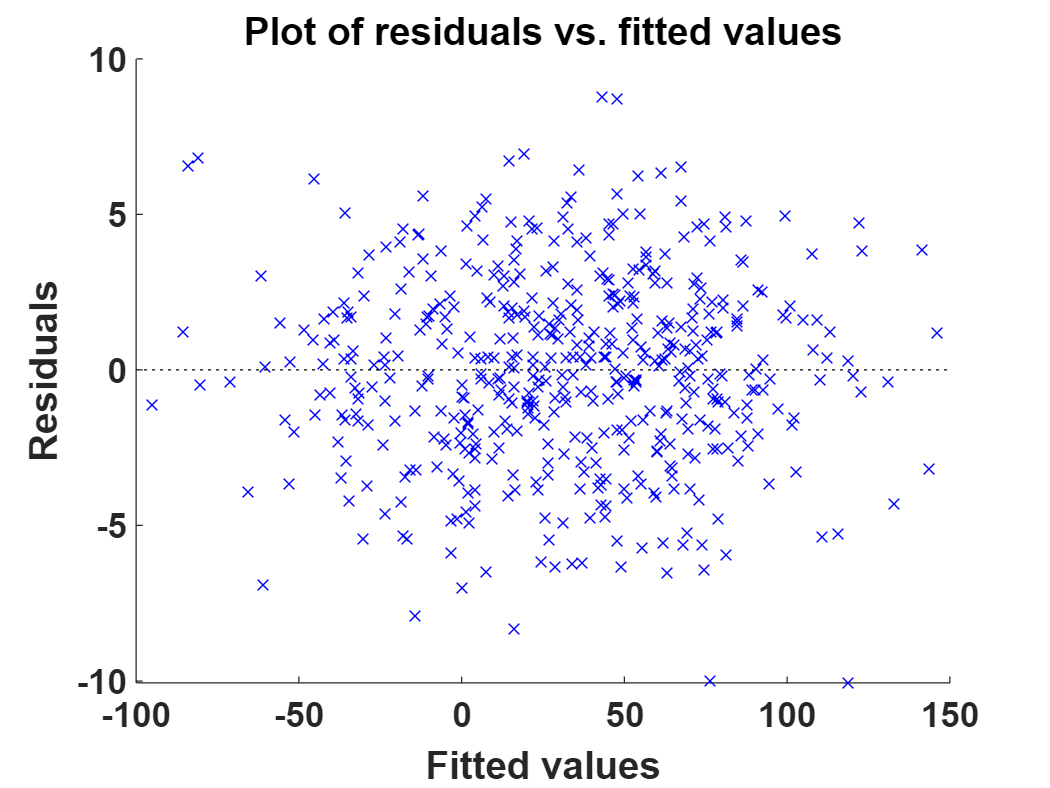

figure
plotResiduals(mdl1,"fitted")
set(gca,'fontsize',14,'fontweight','bold')
box off

We next turn to a histogram and correlation analysis of residuals

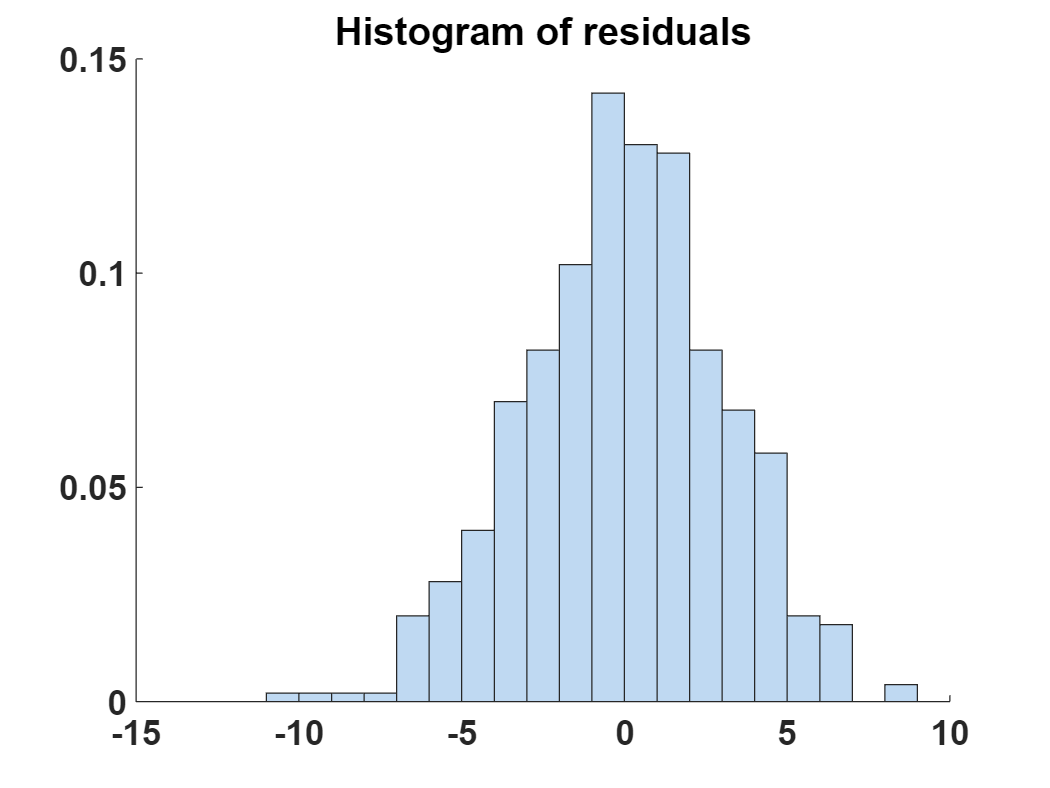

plotResiduals(mdl1,"histogram")
set(gca,'fontsize',14,'fontweight','bold')
box off

There are no distinct pattern in the residual plot and the histogram follows a gaussian distribution indicating the residuals are white.

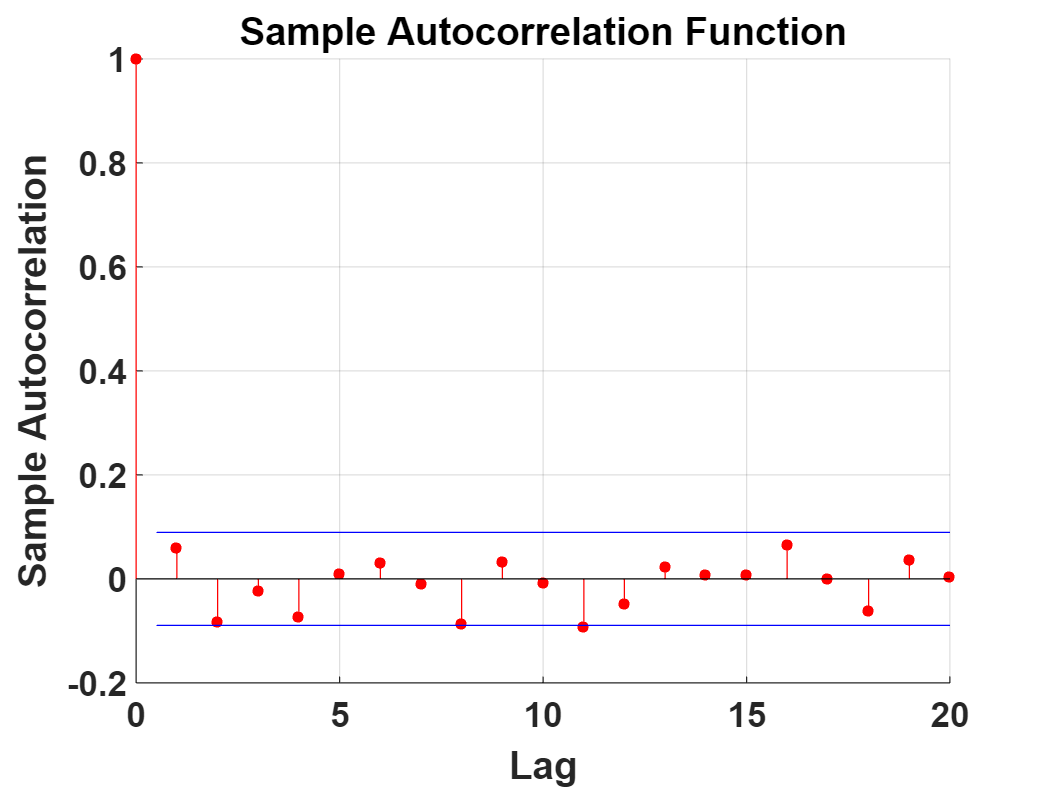


autocorr(mdl1.Residuals.Raw,20)
set(gca,'fontsize',14,'fontweight','bold')
box off

**Q.2)  **In this example we will analyse  the linear regression estimates of  AR(2) model coefficients.

The AR(2) model is given as follows:


$$v\left\lbrack k\right\rbrack =0\ldotp 25v\left\lbrack k-1\right\rbrack +0\ldotp 4v\left\lbrack k-2\right\rbrack +e\left\lbrack k\right\rbrack$$


where, $e\left\lbrack k\right\rbrack$ is white.

The OLS estimator condition states that $\zeta \left\lbrack k\right\rbrack =v-\hat{v} \left\lbrack k\right\rbrack$ should follow strict exogenity given regressors for N time steps.

However, if we use the following predictor to find the LR estimates:

$\hat{v\;} \left\lbrack k\right\rbrack =\alpha_1 v\left\lbrack k-1\right\rbrack$+$\alpha_2 v\left\lbrack k-1\right\rbrack$


$$\zeta \left\lbrack k\right\rbrack =$$

$$v\left\lbrack k\right\rbrack -\;\hat{v\;} \left\lbrack k\right\rbrack$$



$$\begin{array}{l}
\textrm{Let}\;\textrm{us}\;\textrm{take}\;\textrm{two}\;\textrm{instances}\;\textrm{for}\;k=3\;\textrm{and}\;k=4:\\
v\left\lbrack 3\right\rbrack =0\ldotp 25v\left\lbrack 2\right\rbrack +0\ldotp 4v\left\lbrack 1\right\rbrack +e\left\lbrack 3\right\rbrack \\
v\left\lbrack 4\right\rbrack \;=0\ldotp 25\;v\left\lbrack 3\right\rbrack +0\ldotp 4\;v\left\lbrack 1\right\rbrack +e\left\lbrack 3\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;=\left(0\ldotp 25\;v\left\lbrack 2\right\rbrack +0\ldotp 4\;v\left\lbrack 1\right\rbrack +\;e\left\lbrack 3\right\rbrack \right)*0\ldotp 25+0\ldotp 4v\left\lbrack 1\right\rbrack +\mathit{\mathbf{e}}\left\lbrack 4\right\rbrack \\
\hat{v} \;\left\lbrack 3\right\rbrack =\alpha_1 v\left\lbrack 2\right\rbrack +\alpha_2 v\left\lbrack 1\right\rbrack \\
\;\zeta \;\left\lbrack 3\right\rbrack =v\left\lbrack 3\right\rbrack -\hat{v} \;\left\lbrack 3\right\rbrack =0\ldotp 25v\left\lbrack 2\right\rbrack +0\ldotp 4v\left\lbrack 1\right\rbrack -\alpha_1 v\left\lbrack 2\right\rbrack +\alpha_2 v\left\lbrack 1\right\rbrack +e\left\lbrack 3\right\rbrack \\
\hat{v} \;\left\lbrack 4\right\rbrack =\alpha_1 v\left\lbrack 3\right\rbrack +\alpha_2 v\left\lbrack 4\right\rbrack \\
\;\zeta \;\left\lbrack 4\right\rbrack =v\left\lbrack 4\right\rbrack -\hat{v} \;\left\lbrack 4\right\rbrack =0\ldotp 25v\left\lbrack 3\right\rbrack +0\ldotp 4v\left\lbrack 2\right\rbrack -\alpha_1 v\left\lbrack 3\right\rbrack +\alpha_2 v\left\lbrack 2\right\rbrack +e\left\lbrack 4\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left(0\ldotp 25\;v\left\lbrack 2\right\rbrack +0\ldotp 4\;v\left\lbrack 1\right\rbrack +\;e\left\lbrack 3\right\rbrack \right)*0\ldotp 25+0\ldotp 4v\left\lbrack 1\right\rbrack +\mathit{\mathbf{e}}\left\lbrack 4\right\rbrack -\alpha_1 v\left\lbrack 3\right\rbrack +\alpha_2 v\left\lbrack 2\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left(0\ldotp 25\;v\left\lbrack 2\right\rbrack +0\ldotp 4\;v\left\lbrack 1\right\rbrack \right)*0\ldotp 25+0\ldotp 4v\left\lbrack 1\right\rbrack -\alpha_1 v\left\lbrack 3\right\rbrack +\alpha_2 v\left\lbrack 2\right\rbrack +e\left\lbrack 4\right\rbrack +0\ldotp 25e\left\lbrack 3\right\rbrack \\
\textrm{The}\;\textrm{common}\;\textrm{factor}\;\textrm{of}\;e\left\lbrack 3\right\rbrack \;\textrm{between}\;\zeta \left\lbrack 3\right\rbrack \;\textrm{and}\;\zeta \left\lbrack 4\right\rbrack \;\;\textrm{prevents}\;\textrm{strict}\;\textrm{exogenity}\;\ldotp \;\textrm{However},\textrm{we}\;\textrm{will}\;\textrm{see}\;\textrm{in}\;\textrm{the}\;\textrm{example}\;\textrm{asymptotically}\;\zeta \\
\;\textrm{aligns}\;\textrm{with}\;\textrm{the}\;\textrm{conditions}\;\textrm{and}\;\textrm{therefore},\textrm{the}\;\textrm{predictor}\;\textrm{is}\;\textrm{asymptotically}\;\textrm{unbiased}\ldotp 
\end{array}$$


% DATA GENERATING PROCESS
clear;
rng(2);
N=10000;
v=zeros(N,1);
v(1)=0.2;
v(2)=0.15;
e=randn(N-2,1);
for i=3:N-2
v(i)=v(i-1)*0.25+v(i-2)*0.4+e(i-2);
end

% Fitting LR model for different sample size
bias=[];
alpha1=[];
alpha2=[];
for j=10:10:N-2
    x1=v(1:j);
    x2=v(2:j+1);
    y=v(3:j+2);
    mdl=fitlm([x1,x2],y);
    bias=[bias,mdl.Coefficients.Estimate(1)];
    alpha1=[alpha1,mdl.Coefficients.Estimate(2)];
    alpha2=[alpha2,mdl.Coefficients.Estimate(3)];
end

% Model estimates for N=10000
mdl

mdl = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate        SE         tStat       pValue   
                   _________    _________    _______    ___________

    (Intercept)    -0.019225     0.010149    -1.8943       0.058219
    x1                0.4033    0.0091587     44.035              0
    x2               0.24105    0.0091576     26.323    1.0681e-147


Number of observations: 9990, Error degrees of freedom: 9987
Root Mean Squared Error: 1.01
R-squared: 0.299,  Adjusted R-Squared: 0.299
F-statistic vs. constant model: 2.13e+03, p-value = 0

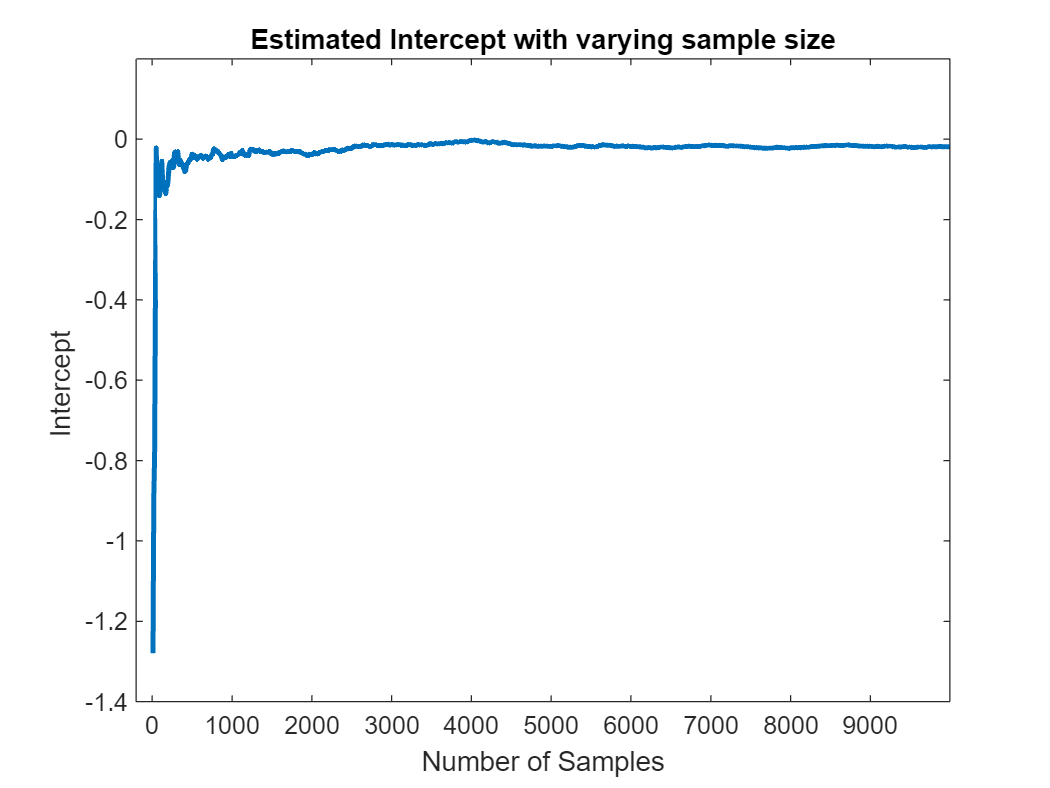

% Checking Consistency in  Intercept estimation
plot(10:10:N-2,bias,linewidth=2)
title("Estimated Intercept with varying sample size")
xlabel("Number of Samples")
ylabel("Intercept ")
xlim([-200,N-2])
ylim([-1.4,0.2])

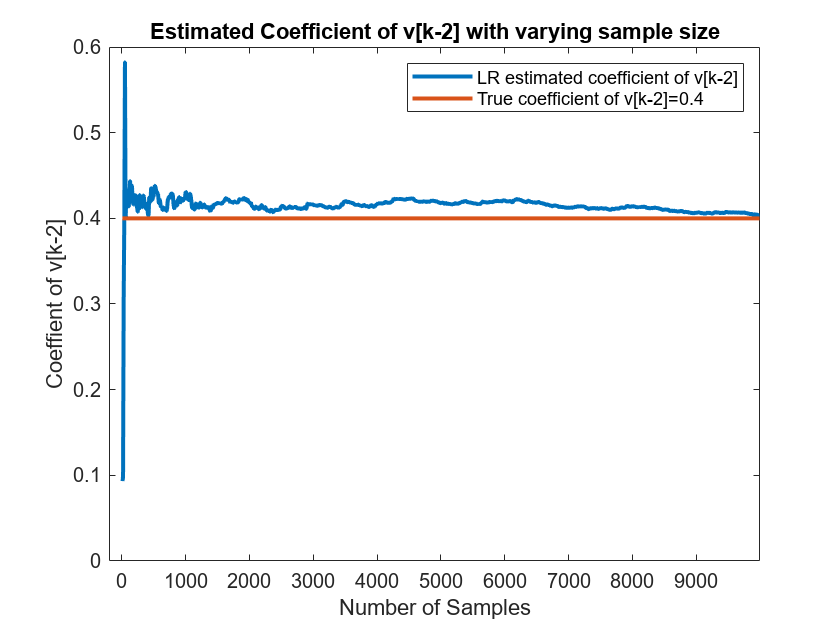

figure
% Checking Constinency in coefficient estimation
plot(10:10:N-2,alpha1,10:10:N-2,ones(j/10,1)*0.4,linewidth=2)
xlim([-200,N-2])
title("Estimated Coefficient of v[k-2] with varying sample size")
xlabel("Number of Samples")
ylabel("Coeffient of v[k-2]")
legend("LR estimated coefficient of v[k-2]", "True coefficient of v[k-2]=0.4")

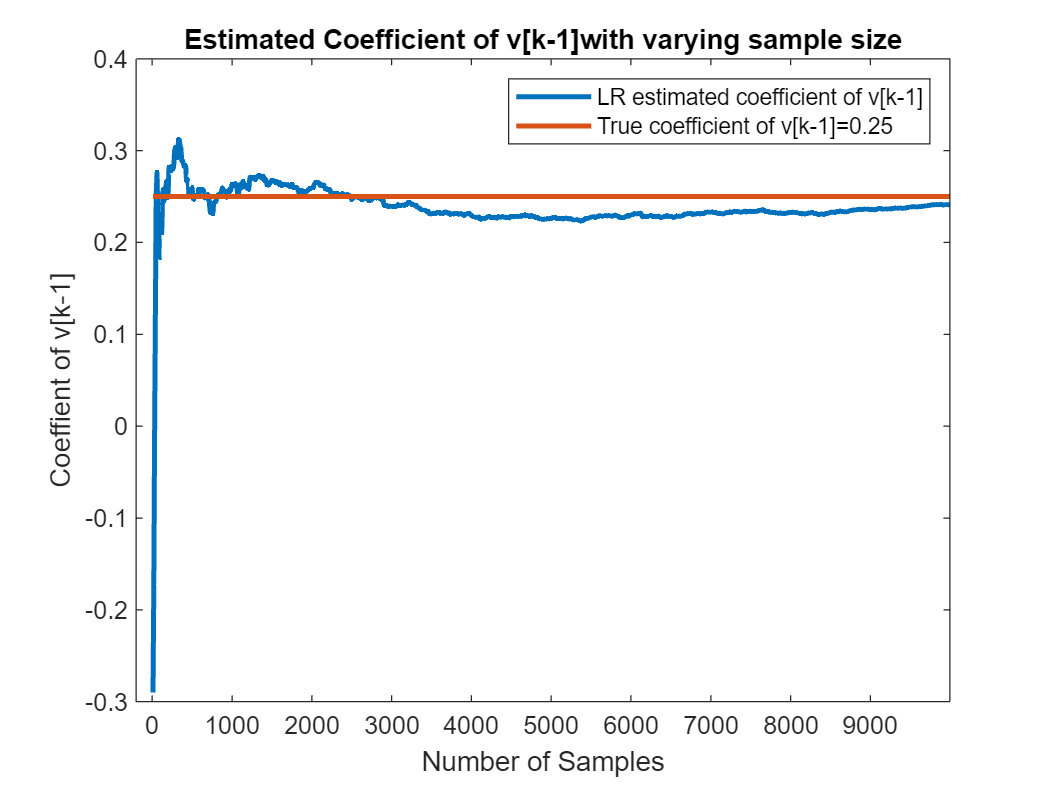

plot(10:10:N-2,alpha2,10:10:N-2,ones(j/10,1)*0.25,linewidth=2)
xlim([-200,N-2])
title("Estimated Coefficient of v[k-1]with varying sample size")
xlabel("Number of Samples")
ylabel("Coeffient of v[k-1]")
legend("LR estimated coefficient of v[k-1]", "True coefficient of v[k-1]=0.25")

% Checking for exogenity condition= sample mean of prediction error given
% regressors for N time steps should be = 0
mu=[];
c=1;
for i= 10:10:N-2
y_hat= v(1:i)*alpha1(c)+v(2:i+1)*alpha2(c);
error= v(3:i+2)-y_hat;
c=c+1;
mu=[mu,mean(error)];
end

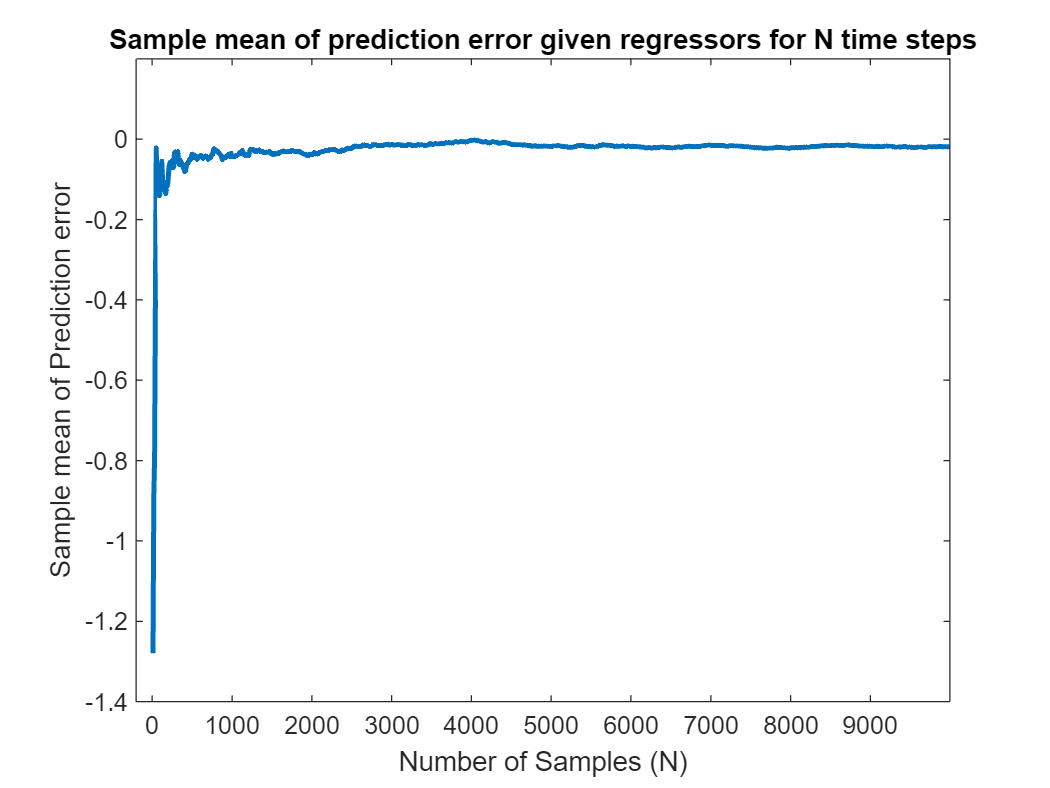

plot(10:10:N-2,mu,linewidth=2)
xlim([-200,N-2])
ylim([-1.4,0.2])
xlabel("Number of Samples (N)")
ylabel("Sample mean of Prediction error")
title("Sample mean of prediction error given regressors for N time steps")

%Sample mean of prediction error(bias) for N=10
mu(1)

ans = -1.2794

%Sample mean of prediction error(bias) for N=10000
mu(end)

ans = -0.0192

**Q 3.) Bias Variance trade off.**


clear;
%Data Generating Process
N=500;
rng(0);
x= 0.2+0.04*(randn(1,N));
y= 0.5+0.08*randn(1,N);
z=0.1+0.1*(randn(1,N));
SNR=5;
v=2*x'+10*y'+15*z';
var_ek=var(v)/SNR;
v=v + normrnd(0,sqrt(var_ek),N,1);


%Declaring artificial regressors
p=400;
phi=randn(N,p-3);%uncorrelated artificial regressors
phi=[x' y' z' phi];

for i=1:p
    model=fitlm(phi(:,1:i),v,Intercept=true);
    v_hat(:,i)=predict(model,phi(:,1:i));% Prediction
    error(:,i)=(v-v_hat(:,i)).^2;% Residuals
    sigma_hat(i)=(sum((error(:,i))));
    tr(i)=sum(model.Coefficients.SE.^2);% Trace of variance from routine    
    SSE(i)=sigma_hat(i)/(N);
end


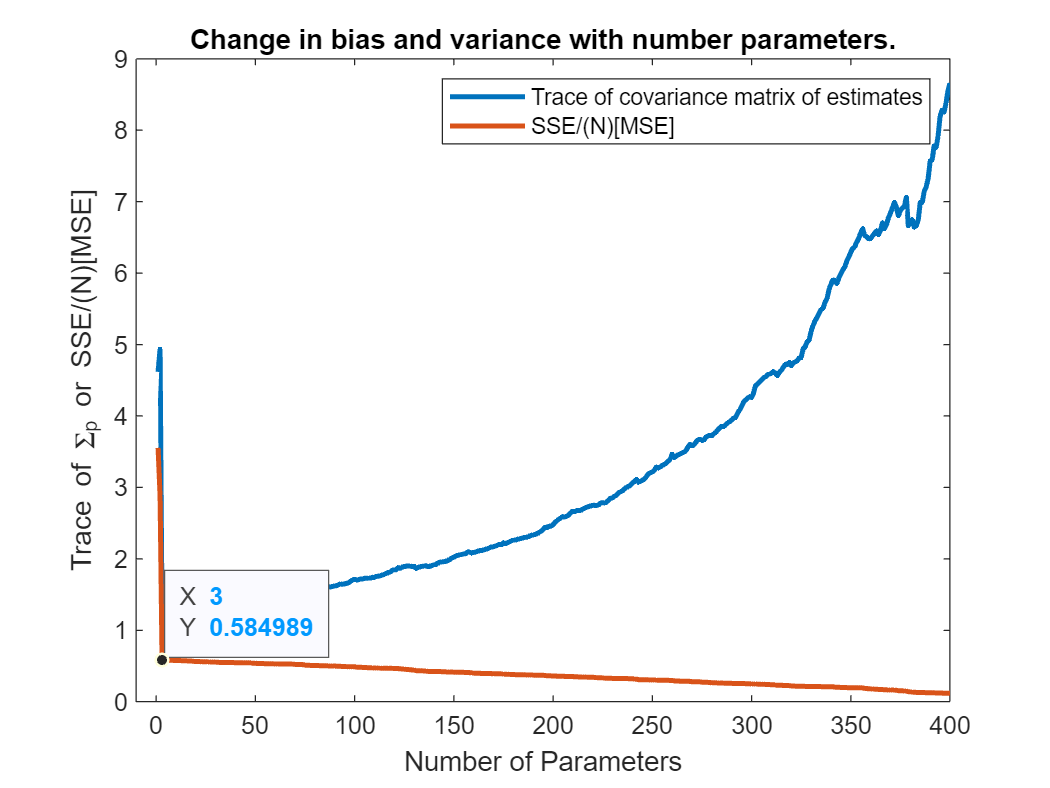

start=1;%Start point holds the true number of parameters
para=start:1:p;
figure
plot(para,tr(start:p),para,SSE(start:p),linewidth=2)
legend("Trace of covariance matrix of estimates","SSE/(N)[MSE]")
xlabel("Number of Parameters")
ylabel("Trace of \Sigma_\theta_p or SSE/(N)[MSE]")
xlim([-10,400])
title("Change in bias and variance with number parameters.")

xlim([-10 400])
ylim([0.00 9.00])
 
SSENMSELine = findobj(gcf, "DisplayName", "SSE/(N)[MSE]");
datatip(SSENMSELine,3,0.585);

Let us separately observe the characteristic graphs when number of parameters in the predictor function is greater than the truth.

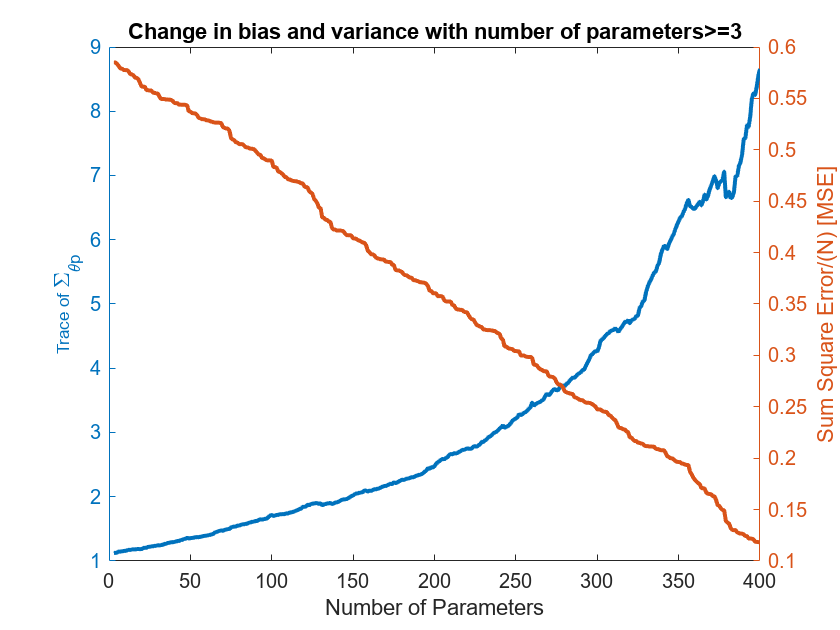

start=3;%Start point holds the true number of parameters
para=start:1:p;
figure
yyaxis right
plot(para,SSE(start:p),linewidth=2)
xlabel("Number of Parameters")
ylabel( "Sum Square Error/(N) [MSE]")
title("Change in bias with number of regressors")
yyaxis left
plot(para,tr(start:p),linewidth=2)
xlabel("Number of Parameters")
ylabel("Trace of \Sigma_\theta_p")
title("Change in variance with number of regressors")
title("Change in bias and variance with number of parameters>=3")

We can view from the above plots that Sum Square Error  decreases as number of parameters  get closer to the number of samples. Whereas, Trace of the covariance matrix of the estimates that gives the sum of the variance in each estimate, and we can see that the variance or the uncertainity in estimates increases as we increase the number of regressors. Thus, a bias-variance trade off is essential to prevent overfitting of model.